%==========================================================================
% Author:    Naghmeh Akhavan, PhD
% Affil.:    University of Michigan
% Contact:   nakhavan@umich.edu
%
% Purpose:
%   Create a pooled scatter plot of inter-REM duration (IREM) versus REM bout
%   duration (REMpre) for Human REM cycles, after applying an in-script
%   long-wake (LW) exclusion rule. The plot includes a least-squares line fit,
%   Pearson correlation (r), an approximate two-sided p-value, and R^2.
%
% Long-wake filtering (in-place):
%   DROP cycles if wake duration meets or exceeds the threshold:
%     - Preferred: any available MaxWake* column (seconds) interpreted as
%       max contiguous wake block (or closest available proxy).
%     - Fallback: total Wake column (seconds) when MaxWake* is unavailable.
%     - If neither exists, no LW filtering is applied (warning issued).
%
% Inclusion (points plotted):
%   After LW filtering, only cycles with REMpre > 0 and IREM > 0 (finite) are
%   included. Durations are converted to minutes for plotting.
%
% Inputs:
%   - combined_out/Combined_BigResultTable.mat (variable: Combined_BigResultTable)
%
% Outputs:
%   - Figure window (optional PNG export; currently commented out)
%
% Notes:
%   - Correlation p-value is computed toolbox-free using Fisher z-transform.
%   - If your table mixes species, ensure only Human rows are present or add
%     an explicit Human filter prior to plotting.
%
% Last updated: 2026-01-16
%==========================================================================

clear; clc;


## Settings (folders + LW threshold)

combinedFolder  = 'C:\Users\naghm\OneDrive\Desktop\combined_out';
outDir          = fullfile(combinedFolder, 'tables_out');
if ~isfolder(outDir), mkdir(outDir); end

WAKE_BREAK_MIN  = 2;                 % minutes
WAKE_BREAK_SEC  = WAKE_BREAK_MIN*60; % seconds


## Load unfiltered table

matAll = fullfile(combinedFolder, 'Combined_BigResultTable.mat');
assert(isfile(matAll), 'Missing %s (run Step 3).', matAll);

S = load(matAll);
assert(isfield(S,'Combined_BigResultTable'), 'MAT lacks Combined_BigResultTable.');
T = S.Combined_BigResultTable;


## Normalize columns (types + derived fields)

T = normalize_cycles_table(T);

% long-wake filtering
vn = string(T.Properties.VariableNames);
maxWakeCandidates = ["MaxWakeSec","MaxWake_s","MaxWakeInIREMSec","MaxWakeInIREM_s","MaxWakeBlockSec","MaxWakeBlock_s"];

if any(ismember(maxWakeCandidates, vn))
    cname = maxWakeCandidates(find(ismember(maxWakeCandidates, vn), 1, 'first'));
    maxWakeSec = double(T.(cname));
    dropFlag = maxWakeSec >= WAKE_BREAK_SEC;
    filterMsg = sprintf("max Wake block '%s' >= %gs", cname, WAKE_BREAK_SEC);
elseif ismember("Wake", vn)
    dropFlag = double(T.Wake) >= WAKE_BREAK_SEC;   % fallback: total Wake in IREM
    filterMsg = sprintf("total Wake (fallback) >= %gs", WAKE_BREAK_SEC);
else
    dropFlag = false(height(T),1);
    filterMsg = "no MaxWake*/Wake — no filtering applied";
    warning('No MaxWake* or Wake column found; no long-wake filtering applied.');
end

% apply the filter and compute counts
Tall     = T;              % keep a reference for totals
T        = T(~dropFlag,:); % kept cycles
TotalAll = height(Tall);
Kept     = height(T);
Dropped  = sum(dropFlag);
DroppedPct = 100 * Dropped / max(TotalAll,1);


## Build pooled arrays (minutes)

REMpre_min = T.REMpre/60;
IREM_min   = T.IREM/60;

% Valid points: positive & finite
valid = isfinite(REMpre_min) & (REMpre_min > 0) & isfinite(IREM_min) & (IREM_min > 0);
fprintf('Total cycles: %d | Kept: %d | Dropped: %d (%.1f%%)  [%s]\n', ...
        TotalAll, Kept, Dropped, DroppedPct, filterMsg);

Total cycles: 5022 | Kept: 3464 | Dropped: 1558 (31.0%)  [total Wake (fallback) >= 120s]



x = IREM_min(valid);   % X-axis = inter-REM [min]
y = REMpre_min(valid); % Y-axis = REMpre    [min]
n = numel(x);
% requires at least two points to fit a line and compute correlation
if n < 2
    error('Not enough valid points after filtering (n=%d).', n);
end


## Simple line fit y = a*x + b

p  = polyfit(x, y, 1);          % [a b]
xx = linspace(min(x), max(x), 300);
yy = polyval(p, xx);


## Pearson r and two-sided p-value and R^2

C  = corrcoef(x, y);  r = C(1,2);
if n >= 4 && abs(r) < 1
    z = atanh(r) * sqrt(n - 3);
    pval = erfc(abs(z)/sqrt(2));
else
    pval = NaN;
end
R2 = r^2;


## Plot

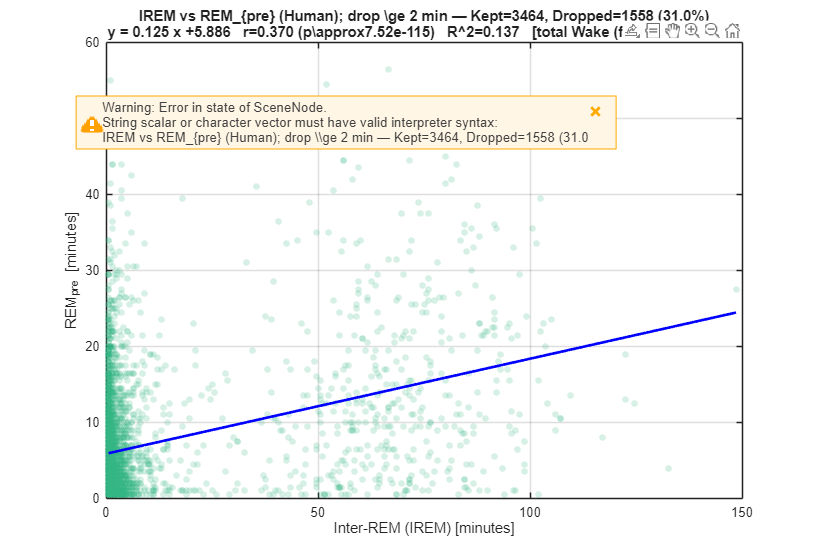

f1 = figure('Color','w','Position',[100 100 820 560], 'Name','Human: IREM vs REMpre');
h = scatter(x, y, 20, [0.20 0.70 0.50], 'filled');
set(h, 'MarkerEdgeColor', [0.20 0.70 0.50], ...
       'MarkerFaceAlpha', 0.20, ...
       'MarkerEdgeAlpha', 0.20);
hold on;
plot(xx, yy, 'b-', 'LineWidth', 2);
grid on; box on;

xlabel('Inter-REM (IREM) [minutes]');
ylabel('REM_{pre} [minutes]');
title(sprintf(['IREM vs REM_{pre} (Human); drop \\ge %d min — Kept=%d, Dropped=%d (%.1f%%)\n' ...
               'y = %.3f x %+.3f   r=%.3f (p\\approx%.3g)   R^2=%.3f   [%s]'], ...
      WAKE_BREAK_MIN, Kept, Dropped, DroppedPct, p(1), p(2), r, pval, R2, filterMsg));


% -------- Optional: save figure --------
% outFig = fullfile(outDir, sprintf('scatter_IREM_vs_REMpre_DROP%gmin.png', WAKE_BREAK_MIN));
% exportgraphics(f1, outFig, 'Resolution', 300);


## Functions

function T = normalize_cycles_table(T)
    % ensure subject and cycle IDs exit and are strings
    if ~ismember("Subject_Index", string(T.Properties.VariableNames))
        T.Subject_Index = strings(height(T),1);
    end
    T.Subject_Index = string(T.Subject_Index);

    if ~ismember("REM_Cycle_Index", string(T.Properties.VariableNames))
        T.REM_Cycle_Index = strings(height(T),1);
    end
    T.REM_Cycle_Index = string(T.REM_Cycle_Index);

    % Source (infer when missing)
    if ~ismember("Source", string(T.Properties.VariableNames))
        T.Source = strings(height(T),1);
    else
        T.Source = string(T.Source);
    end
    % If Source missing, infer based on prefixes
    m = (T.Source=="" | ismissing(T.Source));
    T.Source(m & startsWith(T.Subject_Index,"MNC"))      = "MNC";
    T.Source(m & startsWith(T.Subject_Index,"SC"))       = "EDF";
    T.Source(m & startsWith(T.Subject_Index,"BitBrain")) = "BitBrain";
    T.Source(T.Source=="") = "Unknown";

    % Ensure numeric metric columns exist and are doubles
    need = ["REMpre","NREM","Wake","Movement","IREM"];
    for v = need
        if ~ismember(v, string(T.Properties.VariableNames))
            T.(v) = NaN(height(T),1);
        end
        T.(v) = double(T.(v));
    end
    % Rebuild IREM if needed/missing
    if all(isnan(T.IREM)) && all(ismember(["NREM","Wake","Movement"], string(T.Properties.VariableNames)))
        T.IREM = T.NREM + T.Wake + T.Movement;
    end

    % Species tag
    if ~ismember("Species", string(T.Properties.VariableNames))
        T.Species = repmat("Human", height(T), 1);
    else
        T.Species = string(T.Species);
        T.Species(T.Species=="") = "Human";
    end
end
